Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\User\eeg_options.m
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" v3.7.9 to the path - new version 3.8.1 available
EEGLAB: adding "ICLabel" v1.4 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.8 (see >> help eegplugin_clean_rawdata)
EEGLAB: adding "dipfit" v5.0 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.7.1 (see >> help eegplugin_firfilt)


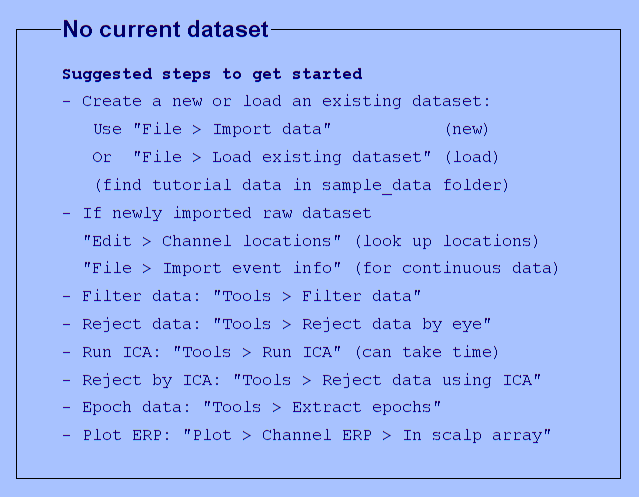

You are using the latest version of EEGLAB.


addpath 'C:\Users\User\Cloud-Drive\BigFiles\libs\eeglab2023.0'
eeglab

import_type ='eventDetectionChan';
referenced_name =  'referenced';

input_dir_epoched = 'C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced';
csv_dir = 'C:\Users\User\Cloud-Drive\BigFiles\OmissionExpOutput\eventDetection\detected_csv';
output_dir = 'C:\Users\User\Cloud-Drive\BigFiles\OmissionExpOutput\eventDetection\updatedEEGLABEvents';

subs = {'01','02','03','04','05','06','07','08','09','10','11','12','13','14','15','16','17','19','20','21','22','23','24','25','26','27','28','29','30','31','32','33','34','35','36','37','38'};

fs = 500; %% of the eventDetection eeg files

epoch_dur = 0.5; % in sec

for sub_ind=1:size(subs,2)
    sleep_files_name_suffix = strcat('_sleep','_',referenced_name,'.set');
    output_filename = strcat(output_dir,'/sub',subs(sub_ind),'_', referenced_name, '_sleepEvents.mat');
    if isfile(output_filename)
        string(strcat('Sub_',subs(sub_ind), ' already exists in path:',  output_filename))
        continue
    end

    %% get epoched file
    try
        set_filename = strcat('s_',subs(sub_ind),'_sleep','_',referenced_name,'.set');
        eeglab_epoched =  pop_loadset(set_filename, input_dir_epoched);
    catch ME
        strcat('could not get ' ,set_filename)
        continue
    end 
    events_epoched = eeglab_epoched.event;

    try
        sleepEvents_epoched_events = addEEGLABEvent_sleepEvents(subs(sub_ind),epoch_dur,fs,events_epoched,csv_dir);
    catch ME
        strcat('could not preform addEEGLABEvent_sleepEvents for sub ' ,subs(sub_ind))
        continue
    end
    
    %% Save the new eeglab event struct
    if ~isfolder(output_dir)
        mkdir(output_dir)
    end
    save(output_filename{1},"sleepEvents_epoched_events");
end

pop_loadset(): loading file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_01_sleep_referenced.set ...
Reading float file 'C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_01_sleep_referenced.fdt'...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_loadset(): loading file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_02_sleep_referenced.set ...
Reading float file 'C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_02_sleep_referenced.fdt'...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_loadset(): loading file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_03_sleep_referenced.set ...
Reading float file 'C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_03_sleep_referenced.fdt'...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_loadset(): loading file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_04_sleep_referenced.set ...
Reading float file 'C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_04_sleep_referenced.fdt'...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_loadset(): loading file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_05_sleep_referenced.set ...
Reading float file 'C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_05_sleep_referenced.fdt'...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_loadset(): loading file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_06_sleep_referenced.set ...
Reading float file 'C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_06_sleep_referenced.fdt'...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_loadset(): loading file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_07_sleep_referenced.set ...
Reading float file 'C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_07_sleep_referenced.fdt'...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_loadset(): loading file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_08_sleep_referenced.set ...
Reading float file 'C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_08_sleep_referenced.fdt'...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_loadset(): loading file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_09_sleep_referenced.set ...
Reading float file 'C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_09_sleep_referenced.fdt'...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_loadset(): loading file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_10_sleep_referenced.set ...
Reading float file 'C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_10_sleep_referenced.fdt'...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_loadset(): loading file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_11_sleep_referenced.set ...
Reading float file 'C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_11_sleep_referenced.fdt'...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


ans = 1×1 cell array
    {'could not preform addEEGLABEvent_sleepEvents for sub11'}


pop_loadset(): loading file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_12_sleep_referenced.set ...
Reading float file 'C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_12_sleep_referenced.fdt'...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_loadset(): loading file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_13_sleep_referenced.set ...
Reading float file 'C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_13_sleep_referenced.fdt'...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_loadset(): loading file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_14_sleep_referenced.set ...
Reading float file 'C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_14_sleep_referenced.fdt'...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_loadset(): loading file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_15_sleep_referenced.set ...
Reading float file 'C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_15_sleep_referenced.fdt'...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_loadset(): loading file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_16_sleep_referenced.set ...
Reading float file 'C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_16_sleep_referenced.fdt'...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_loadset(): loading file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_17_sleep_referenced.set ...
Reading float file 'C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_17_sleep_referenced.fdt'...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_loadset(): loading file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_19_sleep_referenced.set ...
Reading float file 'C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_19_sleep_referenced.fdt'...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_loadset(): loading file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_20_sleep_referenced.set ...
Reading float file 'C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_20_sleep_referenced.fdt'...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_loadset(): loading file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_21_sleep_referenced.set ...
Reading float file 'C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_21_sleep_referenced.fdt'...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_loadset(): loading file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_22_sleep_referenced.set ...
Reading float file 'C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_22_sleep_referenced.fdt'...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_loadset(): loading file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_23_sleep_referenced.set ...
Reading float file 'C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_23_sleep_referenced.fdt'...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_loadset(): loading file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_24_sleep_referenced.set ...
Reading float file 'C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_24_sleep_referenced.fdt'...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_loadset(): loading file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_25_sleep_referenced.set ...
Reading float file 'C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_25_sleep_referenced.fdt'...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_loadset(): loading file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_26_sleep_referenced.set ...
Reading float file 'C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_26_sleep_referenced.fdt'...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_loadset(): loading file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_27_sleep_referenced.set ...
Reading float file 'C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_27_sleep_referenced.fdt'...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_loadset(): loading file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_28_sleep_referenced.set ...
Reading float file 'C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_28_sleep_referenced.fdt'...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_loadset(): loading file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_29_sleep_referenced.set ...
Reading float file 'C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_29_sleep_referenced.fdt'...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_loadset(): loading file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_30_sleep_referenced.set ...
Reading float file 'C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_30_sleep_referenced.fdt'...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_loadset(): loading file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_31_sleep_referenced.set ...
Reading float file 'C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_31_sleep_referenced.fdt'...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_loadset(): loading file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_32_sleep_referenced.set ...
Reading float file 'C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_32_sleep_referenced.fdt'...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_loadset(): loading file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_33_sleep_referenced.set ...
Reading float file 'C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_33_sleep_referenced.fdt'...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_loadset(): loading file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_34_sleep_referenced.set ...
Reading float file 'C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_34_sleep_referenced.fdt'...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_loadset(): loading file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_35_sleep_referenced.set ...
Reading float file 'C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_35_sleep_referenced.fdt'...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_loadset(): loading file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_36_sleep_referenced.set ...
Reading float file 'C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_36_sleep_referenced.fdt'...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_loadset(): loading file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_37_sleep_referenced.set ...
Reading float file 'C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_37_sleep_referenced.fdt'...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_loadset(): loading file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_38_sleep_referenced.set ...
Reading float file 'C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_38_sleep_referenced.fdt'...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


function [new_epoched_event] = addEEGLABEvent_sleepEvents(sub,epoch_dur,fs,events_epoched,csv_dir)
    % Initialize new_epoched_event struct
    add_columns = {'preEpoched_filenum', ... %% preEpoched_filenum is depracted!! now you have 'ses_file_num'. question this whole function!
                    'is_ss','ss_start_t','ss_end_t','ss_power',...
                    'is_kc','kc_start_t','kc_end_t','kc_amp'};
    new_epoched_event = events_epoched;
    zeros = cell(1,size(events_epoched,2));
    zeros(:) = {0};
    for i=1:size(add_columns,2)
        [new_epoched_event.(add_columns{i})] = zeros{:};
    end
    
    % assosiate each event with preEpoched file
    curr_nonepoched_file = 1;
    epoched_initTime = [events_epoched.init_time];
    new_epoched_event(1).('preEpoched_filenum') = 1;
    for epoched_i=2:size(events_epoched,2)
        if epoched_initTime(epoched_i - 1) > epoched_initTime(epoched_i)
            curr_nonepoched_file = curr_nonepoched_file + 1;
        end
        new_epoched_event(epoched_i).('preEpoched_filenum') = curr_nonepoched_file;
    end

    % load ss detected events
    curr_event_filename = strcat(csv_dir,'\sub-',sub,'_SS-[4, 10, 1].csv');
    curr_ss_events = readtable(curr_event_filename{1});
    % show time in sec
    curr_ss_events.spindleStartTime = curr_ss_events.spindleStartTime / fs;
    curr_ss_events.spindleEndTime = curr_ss_events.spindleEndTime / fs;
    curr_ss_events.peakTime = curr_ss_events.peakTime / fs;
    
    % populate event table with ss details
    for epoched_i=2:size(events_epoched,2)
        % look for event in curr epoch
        eventsInEpochTime = curr_ss_events(curr_ss_events.subfile == new_epoched_event(epoched_i).('preEpoched_filenum') ...
                                & curr_ss_events.spindleStartTime <= epoched_initTime(epoched_i)+epoch_dur ...
                                & curr_ss_events.spindleEndTime >= epoched_initTime(epoched_i)...
                                , :);
        if size(eventsInEpochTime,1) > 0
            new_epoched_event(epoched_i).('ss_start_t') = eventsInEpochTime.spindleStartTime(1) - epoched_initTime(epoched_i);
            new_epoched_event(epoched_i).('ss_end_t') = eventsInEpochTime.spindleEndTime(1) - epoched_initTime(epoched_i) ;
            new_epoched_event(epoched_i).('ss_power') = eventsInEpochTime.PowerSP(1);
            new_epoched_event(epoched_i).('is_ss') = 1;
        end
    end
    
    % load kcomp detected events
    curr_event_filename = strcat(csv_dir,'\sub-',sub,'_KComp.csv');
    curr_kcomp_events = readtable(curr_event_filename{1},'VariableNamingRule','preserve');
    % show time in sec
    curr_kcomp_events.pos_i = curr_kcomp_events.pos_i / fs;
    curr_kcomp_events.neg_i = curr_kcomp_events.neg_i / fs;
    curr_kcomp_events.estim_duration = (curr_kcomp_events.pos_i - curr_kcomp_events.neg_i) * 2;
    curr_kcomp_events.estim_start = curr_kcomp_events.neg_i - (curr_kcomp_events.estim_duration/4);
    curr_kcomp_events.estim_end = curr_kcomp_events.pos_i + (curr_kcomp_events.estim_duration/4);
    
    % populate event table with kcomp details
    for epoched_i=2:size(events_epoched,2)
        % look for event in curr epoch
        eventsInEpochTime = curr_kcomp_events(curr_kcomp_events.subfile == new_epoched_event(epoched_i).('preEpoched_filenum') ...
                                & curr_kcomp_events.estim_start <= epoched_initTime(epoched_i)+epoch_dur ...
                                & curr_kcomp_events.estim_end >= epoched_initTime(epoched_i)...
                                , :);
        if size(eventsInEpochTime,1) > 0
            new_epoched_event(epoched_i).('kc_start_t') = eventsInEpochTime.estim_start(1)- epoched_initTime(epoched_i);
            new_epoched_event(epoched_i).('kc_end_t') = eventsInEpochTime.estim_end(1) - epoched_initTime(epoched_i);
            new_epoched_event(epoched_i).('kc_amp') = eventsInEpochTime.power(1);
            new_epoched_event(epoched_i).('is_kc') = 1;
        end
    end
end